## Relational Operators

#### Scalars

A = 5;
A > 42

ans = logical
   0


B = -10;
B <= -10

ans = logical
   1


C = 10;
D = 3;
C == D^2

ans = logical
   0


V = 120;
V < 4/3*pi*6.72^3

ans = logical
   1


L1 = 1;
L2 = 3;
D ~= L1*L2

ans = logical
   0


#### Matrices

X = [2 0 -4 6];
Y = [3 6; -1 9];
Z = [4 0 1 -9; 3 -4 -3 8];
X < 1

ans = 1×4 logical array
   0   1   1   0


Z(2,:) <= X

ans = 1×4 logical array
   0   1   0   0


%Y == Y'
%X <= Y


## Using Conditions - find Function

Loc = find([0 1 0 0 1]) %tell what index is, finds the non zero entries

Loc =      2     5


S=randi(100,3,3) % creating random matrix with values between 1 and 100

S =     35    74    26
    43    94    31
    12    74    36


[Row,Col] = find(S>75)

Row =      2


Col =      2


## Floating Point Error

format long %gives 15 decimals
x = 1.6 %by default will give 4 decimal places

x =    1.600000000000000


fprintf('%0.17f',x) % Displays value to 17 decimal places 

1.60000000000000009

%doc display format for numeric values

x = 1.5;
y = 3;

y == (3.2*x)/1.6

ans = logical
   0


y == round((3.2*x)/1.6)

ans = logical
   1


fprintf('%0.16f\n',y)

3.0000000000000000


fprintf('%0.16f\n',3.2*x/1.6) %slightly different

3.0000000000000004


## strcmp and strcmpi 

A = upper('yes')

A = 'YES'


A == 'yes' %compares each character in the character array

ans = 1×3 logical array
   0   0   0


%A == 'yesssss' %incompatable size so error

strcmp(A,'yes') %look at whole array and see if two are the same, say not = because case sensitive

ans = logical
   0


strcmpi(A,'yes') %see if imputs are the same

ans = logical
   1


## Logical Operators

**called short circuit operators, only work on scalars**

**AND BEFORE OR**

**and (&&) A&&B, a and b will be zero or 1, 4 combos of it**

**a b output**

**0 0 0**

**0 1 0**

**1 0 0**

**1 1 1 **

**only get a 1 output if both are 1**

**or (||)**

**A||B**

**a b output**

**0 0 0**

**0 1 1**

**1 0 1**

**1 1 1 **

**not ~A**

**0 1**

**1 0**

**reverses if true/false**

**code for resistance Rx not w/i 1% of specific value**

R0=1

R0 =      1


rx=1.0

rx =      1


Val=~(rx>=.99*R0&&rx<=1.01*R0)

Val = logical
   0


Stream=rx<=.99*R0||rx>=1.01*R0

Stream = logical
   0



p=4 %any value will make it true

p =      4


%order of importance, && has importance over ||
(p>0)||(p~=3)&&(p<=5)

ans = logical
   1



p>0&&p~=3&&p<=5

ans = logical
   1


% works for values 1 2 4 5
 L = 5

L =      5


M = 5

M =      5


L < 8 && M > 4

ans = logical
   1


L < 8 && M > 6

ans = logical
   0


L ~= 5 && M > 6

ans = logical
   0


L < 8 || M > 4

ans = logical
   1


L < 8 || M > 6

ans = logical
   1


L ~= 5 || M > 6

ans = logical
   0


L >= 5

ans = logical
   1


~(L >= 5)

ans = logical
   0


## Temperature Example 1

At one atmosphere of pressure, water changes phases based upon temperature.

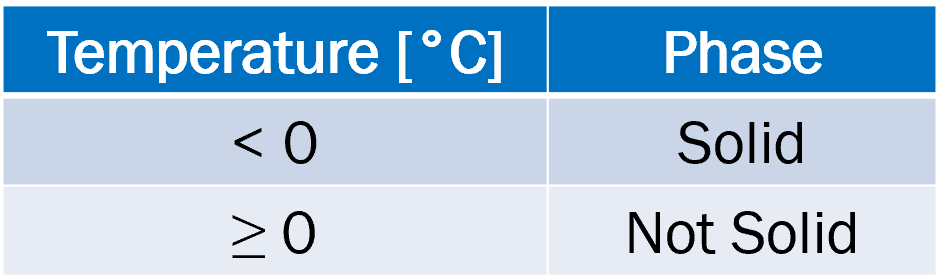

Insert an image of your algorithm:

Write a program which will determine the phase of water given the temperature specified by the user in degrees Fahrenheit [°F]. Store the phase of water as a character array stored in the variable named `phase`.

T = 45, % F - input user can change

T =     45


TC=(T-35)/1.8;
if TC<0
   TP= 'solid'
else
    TP='Not solid'
end

TP = 'Not solid'



M9=5

M9 =      5


if M9<0
    M9=M9+3
end
%nothing happens for else

## Temperature - Example 2

At one atmosphere of pressure, water changes phases based upon temperature.

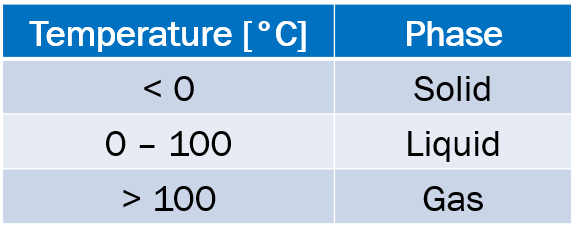

Insert an image of your algorithm:

Write a program which will determine the phase of water given the temperature specified by the user in degrees Fahrenheit [°F]. Store the phase of water as a character array stored in the variable named `phase`.

T = 20 % F - input user can change

T =     20


T=(T-35)/1.8;
if T>100
    Phase='gas'
elseif T>0&&T<100
    Phase='liquid'
else T<0
    Phase='solid'
end 

ans = logical
   1


Phase = 'solid'



Temp=randi([-300,300],[1,1])

Temp =     52


pressure=([-2,3],[1,1])
if temp>0
